# Evaluate and Improve the Fit

This code loads ocean buoy data. 

time=[0 0.42 0.84 1.26 1.68 2.09 2.51 2.93 3.35 3.77 4.19 4.61 5.03 5.45 5.86 6.28]'

time =          0
    0.4200
    0.8400
    1.2600
    1.6800
    2.0900
    2.5100
    2.9300
    3.3500
    3.7700


height=[0.37 0.49 0.48 0.46 0.33 0.1 -0.12 -0.27 -0.37 -0.51 -0.47 -0.42 -0.2 -0.05 0.18 0.37]'

height =     0.3700
    0.4900
    0.4800
    0.4600
    0.3300
    0.1000
   -0.1200
   -0.2700
   -0.3700
   -0.5100


## Task 1

The variables `time` and `height` are column vectors containing the data for the height of an ocean buoy as a function of time.  

 In this activity, you will fit the data with two different polynomials and evaluate the quality of each fit.

Task

Use the `fit` function to fit a quadratic polynomial to the ocean buoy data. Ask for two outputs, and assign them to the variables `fQuad` and `gQuad`. 

[fQuad, gQuad]=fit(time,height,"poly2")

fQuad =      Linear model Poly2:
     fQuad(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =      0.0752  (0.04119, 0.1092)
       p2 =     -0.5609  (-0.7825, -0.3394)
       p3 =      0.7629  (0.463, 1.063)

gQuad = struct with fields:
           sse: 0.5652
       rsquare: 0.7206
           dfe: 13
    adjrsquare: 0.6776
          rmse: 0.2085


## Task 2

The R^2 value of the quadratic model is a property of the goodness of fit `gQuad`. You can access the properties of `gQuad` using dot notation:

`gQuad.``PropertyName`

Task

Extract the R^2 value from `gQuad` and save it in a variable named `r2Quad`.

You may want to leave off the semicolon to see the result.

r2Quad=gQuad.rsquare

r2Quad = 0.7206

## Task 3

The R^2 value of the quadratic model is about 0.72. Ideally, the R^2 value for a "good" model would be above 0.98. 

This indicates that a quadratic model is not a good fit for the data, and you can investigate *how* it's not a good fit by plotting the model and data and visually inspecting the fit.

Task

Visualize the model `fQuad` with the data by using the `plot` function with three inputs.

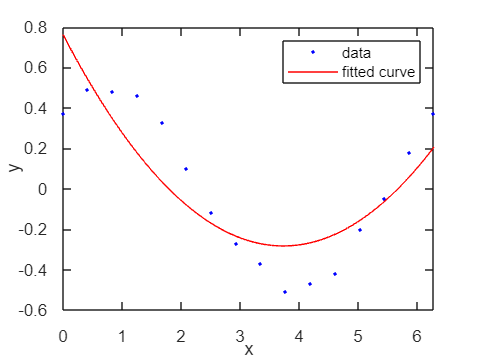

plot(fQuad,time,height)

## Task 4

The quadratic model doesn't appear to be an accurate  representation of the data. The residuals, or the differences between  the actual data and the fit, can help identify patterns or trends that  can be used to improve the model.

You can plot the residuals of a model by using the `plot` function with four inputs.

`plot``(``fitObject``,``xData``,``yData``,``"residuals"``)`

Task

Visualize the residuals of the model `fQuad` by using the `plot` function with four inputs.

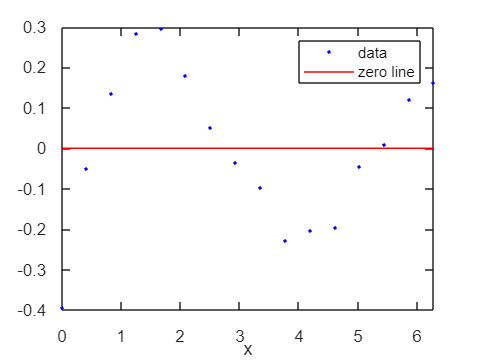

plot(fQuad,time,height,"residuals")

## Task 5

Fit a cubic polynomial to the ocean buoy data by using the `fit` function with the fit type `"poly3"`. Name the two output variables `fCubic` and `gCubic`.

[fCubic,gCubic]=fit(time,height,"poly3")

fCubic =      Linear model Poly3:
     fCubic(x) = p1*x^3 + p2*x^2 + p3*x + p4
     Coefficients (with 95% confidence bounds):
       p1 =      0.0306  (0.02125, 0.03995)
       p2 =      -0.213  (-0.3024, -0.1236)
       p3 =      0.1397  (-0.09723, 0.3766)
       p4 =      0.4564  (0.29, 0.6228)

gCubic = struct with fields:
           sse: 0.1079
       rsquare: 0.9467
           dfe: 12
    adjrsquare: 0.9333
          rmse: 0.0948


## Task 6

Extract the R^2 value from `gCubic` and save it in a variable named `r2Cubic`.

You may want to leave off the semicolon to see the result.

r2Cubic=gCubic.rsquare

r2Cubic = 0.9467

## Task 7

The R^2 value of the cubic model is about 0.94, so the cubic model is a much better fit than the quadratic model.

Task

Plot the cubic model and the data using the `plot` function.

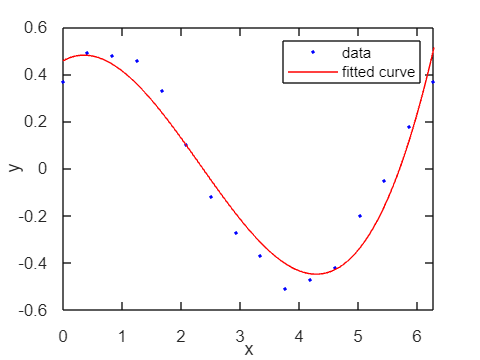

plot(fCubic,time,height)

## Task 8

The cubic model appears to fit the data better, but not exactly. You can get a better look at the fit by plotting the residuals.

Task

Visualize the residuals of the model `fCubic`.

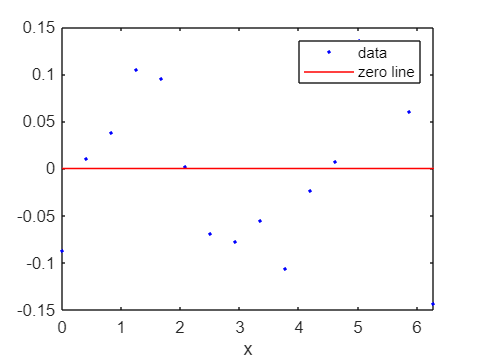

plot(fCubic,time,height,"residuals")

## Further Practice

There is still a detectable pattern in the residuals. This indicates that the fit can be improved.

Try to fit a higher order polynomial to the data by using a fit type such as `"poly4"` or `"poly5"`. How does this affect the R^2

 value and the residuals?

Using higher order polynomials is still linear regression. In the next  lesson, you will investigate nonlinear regression and how it may improve the fit of the ocean buoy data.